clear;clc;
close all;
downloadData = false

downloadData = logical
   0


if downloadData
    websave('feds200628.xls', 'https://www.federalreserve.gov/econresdata/researchdata/feds200628.xls')
end
tb = readtable('feds200628.xls');
tb.Var1 = datetime(tb.Var1);

tt = table2timetable(tb(:,2:end), 'RowTimes', tb.Var1)

tt = 14557×99 timetable
       Time        SVENY01    SVENY02    SVENY03    SVENY04    SVENY05    SVENY06    SVENY07    SVENY08    SVENY09    SVENY10    SVENY11    SVENY12    SVENY13    SVENY14    SVENY15    SVENY16    SVENY17    SVENY18    SVENY19    SVENY20    SVENY21    SVENY22    SVENY23    SVENY24    SVENY25    SVENY26    SVENY27    SVENY28    SVENY29    SVENY30    SVENPY01    SVENPY02    SVENPY03    SVENP

TR = timerange(datetime(1987, 1, 1), datetime(2011, 12, 31));
tt = tt(TR,["SVENY02", "BETA0", "BETA1", "BETA2", "BETA3", "TAU1", "TAU2"]);
tt = retime(tt, 'monthly', 'nearest');
tt(end, :) = [];

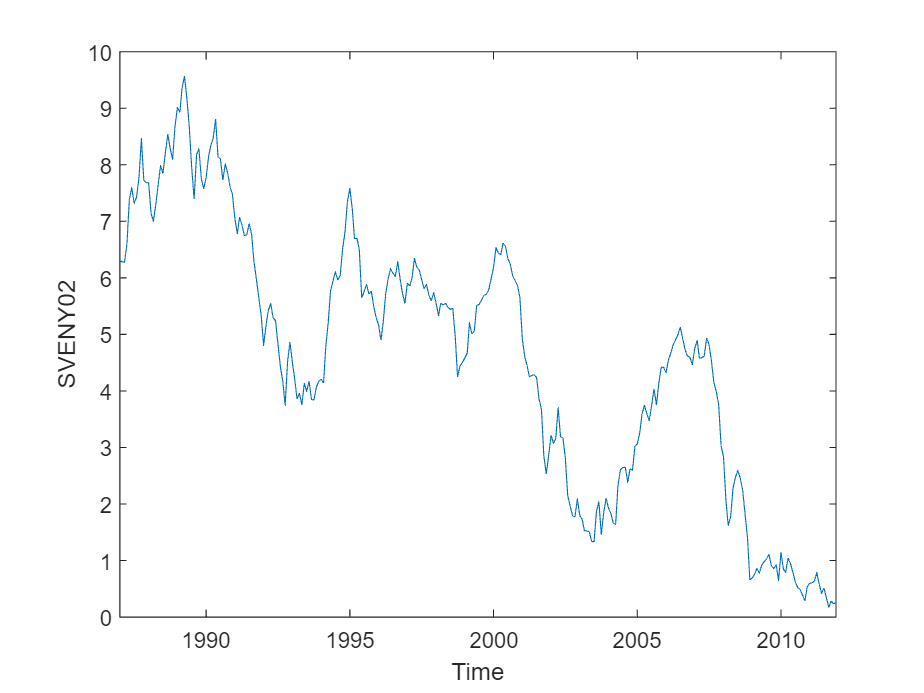

figure; plot(tt, "SVENY02")

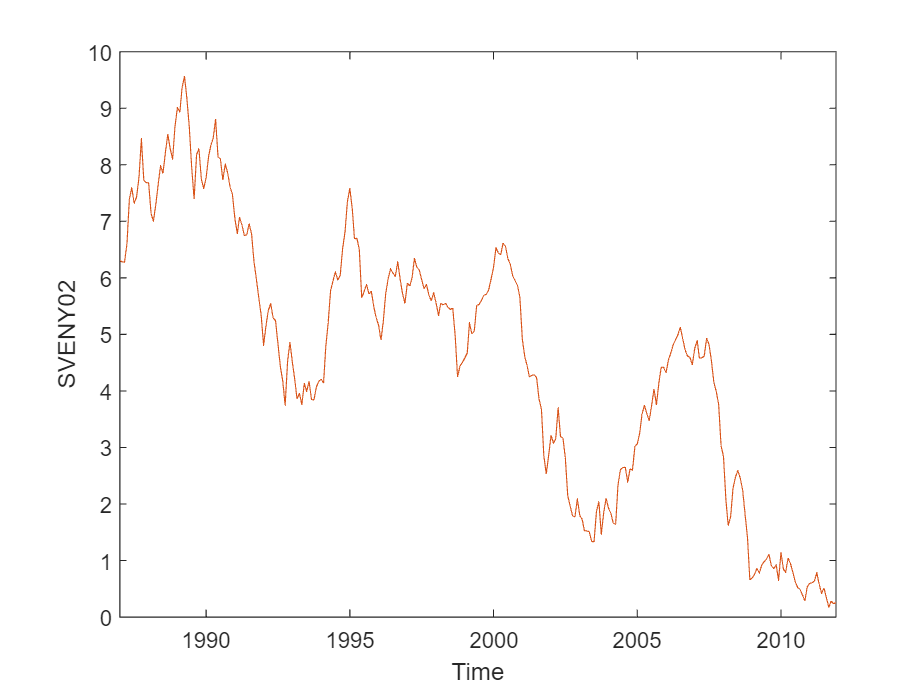

Beta0 = tt.BETA0;
Beta1 = tt.BETA1;
Beta2 = tt.BETA2;
Beta3 = tt.BETA3;
Tau1 = tt.TAU1;
Tau2  = tt.TAU2;
maturities = (1:120)/12;

yields = [];
for i = 1 : height(tt)
    s = Beta0(i) + ...
    Beta1(i).*(1 - exp(-maturities/Tau1(i))).*(Tau1(i)./maturities) + ...
    Beta2(i)*((1-exp(-maturities/Tau1(i))).*Tau1(i)./maturities-exp(-maturities./Tau1(i))) + ...
    Beta3(i)*((1-exp(-maturities./Tau2(i))).*(Tau2(i)./maturities) - exp(-maturities/Tau2(i)));
    yields = [yields; s];
end
ttest = array2timetable(yields, RowTimes=tt.Time);

stir = timetable(ttest{:,1}/12, RowTimes = ttest.Time);
hold on
plot(ttest.Time, ttest{:,24})

% Model options
numFactors = 4;                   % Number of factors

%************************************************************************************************
% Data
%************************************************************************************************
% Specify maturity vectors
nMax    = 120;              % Maximum maturity (in months)
matsAll = 1:nMax;           % Vector of all maturities up to nMax
pcMats  = 3:120;           % Maturities used to compute the pricing factors
rxMats  = [6:6:60,84,120];  % Maturities used for the return regressions
nrx     = size(rxMats,2);   % Number of excess returns in the return regressions
model   = "benchmark";      % Type of model

decomposition = estimateACM(...
    ttest, ...
    stir, ...
    matsAll, ...
    numFactors, ...
    pcMats = pcMats, ...
    rxMats = rxMats, ...
    model = model)

decomposition = struct with fields:
           yHat: [120×300 double]
       expected: [120×300 double]
    riskPremium: [120×300 double]
      convexity: [120×300 double]
        lambda0: [4×1 double]
        lambda1: [4×4 double]


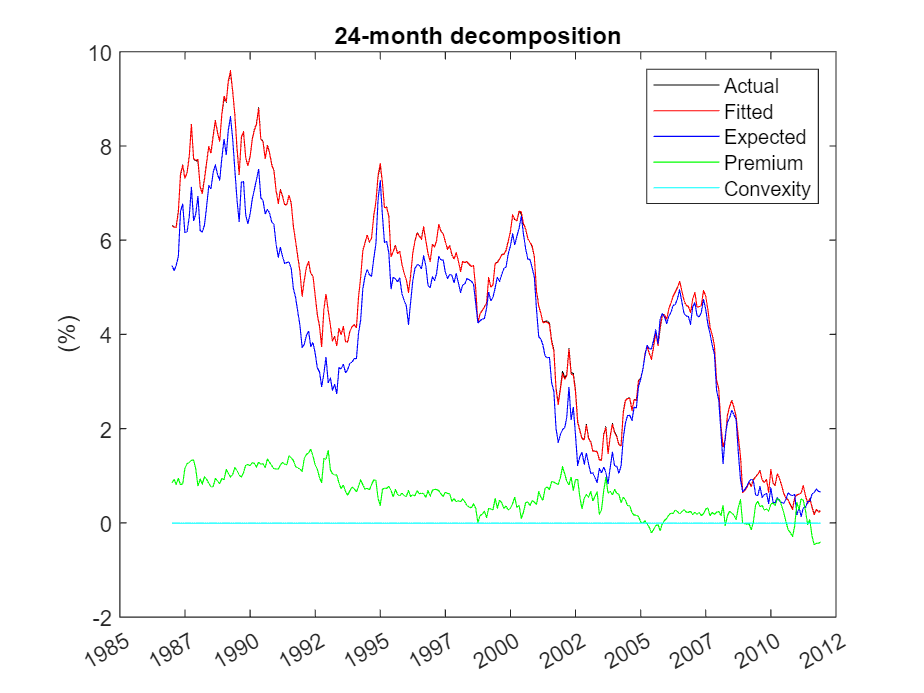


% Plot i-month decomposition
i = 24;
figure
plot(tt.Time,ttest{:,i},'k')
hold on
plot(tt.Time,decomposition.yHat(i,:),'r')
plot(tt.Time,decomposition.expected(i,:),'b')
plot(tt.Time,decomposition.riskPremium(i,:),'g')
plot(tt.Time,decomposition.convexity(i,:),'c')
legend('Actual','Fitted','Expected','Premium','Convexity')
ylabel('(%)')
datetick('x','yyyy')
title(i + "-month decomposition")

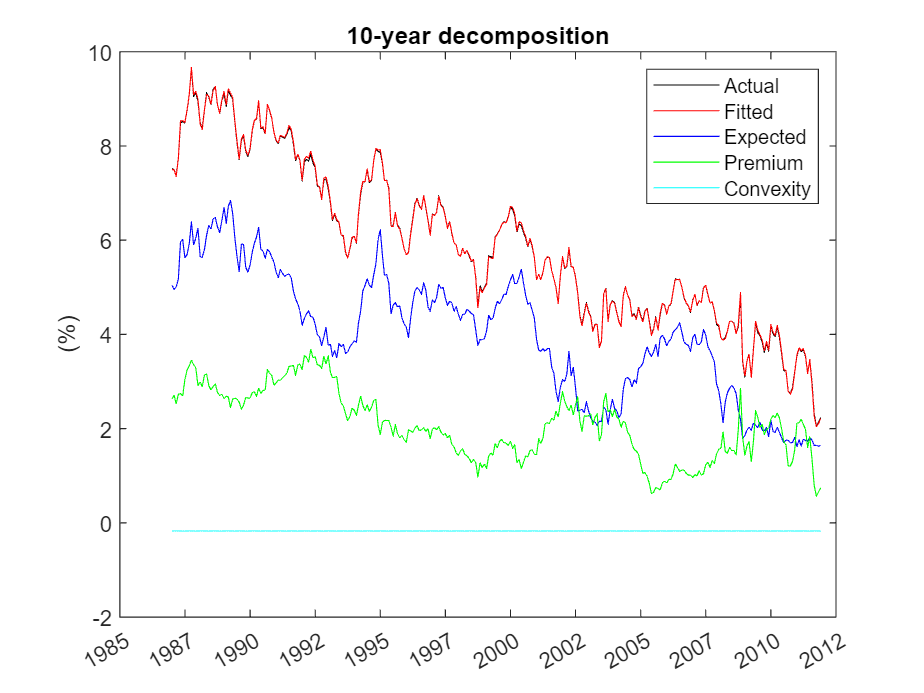

% Plot 10-year decomposition
figure
plot(tt.Time,ttest{:, end},'k')
hold on
plot(tt.Time,decomposition.yHat(end,:),'r')
plot(tt.Time,decomposition.expected(end,:),'b')
plot(tt.Time,decomposition.riskPremium(end,:),'g')
plot(tt.Time,decomposition.convexity(end,:),'c')
legend('Actual','Fitted','Expected','Premium','Convexity')
ylabel('(%)')
datetick('x','yyyy')
title('10-year decomposition')